# ACTIVE Radar Data - Processing Data to Output SNR

### This script will, for ACTIVE input data:

- Uses func slice_SNR to calculate the peak power, the noise (how?), the SNR, and the index of the peak power.  

- Generate a Range-Doppler for the defined slice within the input data.

- Plot a large white diamond marker where the peak power is represented in the Range-Doppler.

- Saves the figure as a .PNG

#### Preperation of data

Clear current workspace dialogue box

% Display a dialog box with three options
choice = questdlg('Do you want to clear the Workspace?', ...
    'Clear Workspace?', 'Yes', ...
    'No', 'No');

% Process user's choice
switch choice
    case 'Yes'
        disp('Workspace cleared');
        % Add code for Option 1 here
        clear
    case 'No'
        disp('Workspace not cleared');
        % Add code for Option 2 here
    otherwise
        % Add code for handling other cases
        disp('User closed the dialog without selecting an option.');
        error('Error. Active data Workspace dialogue box.')
        % Add code for handling other cases
end

Workspace cleared


#### Preparation of Data Storage Directory

This defines where all data generated from this script will be stored. Sub-folders are also created.

% Display a dialog box with three options
choice = questdlg('Select which device you are operating:', ...
    'User to Select Device', 'Rikki - MacBook', ...
    'Jacob - Laptop', 'Rikki - UCL', 'Rikki - MacBook');
% Initialise variable
pc = [];

% Process user's choice
switch choice
    case 'Rikki - MacBook'
        disp('Rikki - MacBook');
        % Add code for Option 1 here
        pc = 1;
        addpath '/Users/rikkimasson/Documents/MATLAB/experiment_data/2'
        addpath '/Users/rikkimasson/Documents/GitHub/bladeRAD-Rikki/generic_scripts/matlab'
        local_save_directory = "/Users/rikkimasson/Documents/MATLAB/experiment_data/";
        repo_directory = "/Users/rikkimasson/Documents/GitHub";
    case 'Jacob - Laptop'
        disp('Jacob - Laptop');
        % Add code for Option 2 here
        pc = 2
        local_save_directory = "C:\Users\jster\OneDrive - University College London\Processing Project Jacob + Rikki\Data Files";
        repo_directory = "D:\GitHub Repos";
    case 'Rikki - UCL'
        disp('Rikki - UCL');
        % Add code for Option 3 here
        pc = 3
        local_save_directory = "C:\Users\uceerm6\OneDrive - University College London\Documents\Radar_Data\beasley_bladeRAD\";
        repo_directory = "C:\Users\uceerm6\OneDrive - University College London\Documents\GitHub";
    otherwise
        % Add code for handling other cases
        disp('User closed the dialog without selecting an option.');
        error('Error. Active data device selection dialogue box.')
        % Add code for handling other cases
end

Rikki - MacBook


Load workspace

load('my_workspace_baseline_23Jan.mat') % define workspace

Prepare Data

inputstructure = active; % define your data input structure
inputstructure.name = "Active"; % define your data input name

active_inputdata = inputstructure.range_doppler_slices;
% User defined ROI indices
active_roi_indices_rows = 320:420; % input to slice_SNR func to calculate noise of roi
active_roi_indices_cols = 65:99;   % input to slice_SNR func to calculate noise of roi
active_signal=zeros(1,length(active_inputdata)); % [dB] once func populates
active_noise=zeros(1,length(active_inputdata)); % [dB] once func populates
active_noise_abs=zeros(1,length(active_inputdata)); % absolute mean noise (not dB) once func populates
active_SNR=zeros(1,length(active_inputdata)); % [dB] once func populates
active_slices_range_doppler = createArrays(length(active_inputdata), size(active_inputdata{1,1})); % [dB] once func populates
active_slices_range_doppler_abs = createArrays(length(active_inputdata), size(active_inputdata{1,1})); % absolute not dB, once func populates
active_signal_idx = zeros(1,length(active_inputdata));

for i=1:length(active_inputdata)
    [active_signal(i),...
        active_noise(i),...
        active_SNR(i),...
        active_slices_range_doppler{i},...
        active_signal_idx(i),...
        active_noise_abs(i),...
        active_slices_range_doppler_abs{i}]=slice_SNR(active_inputdata{1,i}, active_roi_indices_rows, active_roi_indices_cols);
end   

### User to Define which range doppler slice to visualise:

k = 73; % define which slice number you want to visualise

#### Preparation of Data Storage Directory

This defines where all data generated from this script will be stored. Sub-folders are also created.

if pc ==1
    experiment_directory = local_save_directory + experiment_number;
    mkdir(experiment_directory); % create directory
    video_directory = experiment_directory + bracket + "videos";
    mkdir(video_directory); % create directory
    figure_directory = experiment_directory + bracket + "figures";
    mkdir(figure_directory); % create directory
elseif pc ==2
    display('pc 2 data storage directories to be defined by User')
elseif pc ==3
    display('pc 3 data storage directories to be defined by User')
else
    display('Undefined by User')
end    

Return row and column index positions for the peak signal for each slice. Convert index row and column into doppler and range using active. axis and store for each slice.

active_idx_range_axis = zeros(1, length(active_slices_range_doppler));
active_idx_doppler_axis = zeros(1, length(active_slices_range_doppler));

for i = 1:length(active_slices_range_doppler)
    [idx_doppler, idx_range] = ind2sub(size(active_slices_range_doppler{1,i}), active_signal_idx(i));
    % Convert index row and column into doppler and range using active. axis
    active_idx_range_axis(i) = inputstructure.range_axis(idx_range);
    active_idx_doppler_axis(i) = inputstructure.doppler_axis(idx_doppler);
end

Define Range-Doppler user input configuration

x = inputstructure.range_axis; % x_axis
y = inputstructure.doppler_axis; % .doppler_axis is doppler frequency [Hz] % doppler_velocity_axis; % y_axis
dynamic_range = +inf % +50; % user defined dynamic range to maximise visualisation

dynamic_range = Inf

max_range = 500 % user defined max range to maximise visualisation

max_range = 500

max_doppler = 500 % user defined max doppler to maximise visualisation

max_doppler = 500

Generate Range-Doppler image with scaled colours

figure
figure_title = (inputstructure.name + ' Range Doppler Slice ' ...
    + k + ' of ' + length(active_inputdata));
fig = figure;
imagesc(x,y,active_slices_range_doppler{1, k},[-dynamic_range 0])
title(figure_title);
ylabel('Doppler Frequency [Hz]');
xlabel('Range (m)') ;

User to define limits of the colorbar

clim([-100 0]) % -dynamic_range
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;
hold on

Plot peak signal for chosen slice (k) on top of Range-Doppler as large white diamond.

plot(active_idx_range_axis(k), active_idx_doppler_axis(k)...
    , "diamondk", "MarkerFaceColor","w",...
    'MarkerSize', 10)
hold off

Save generated image as .PNG

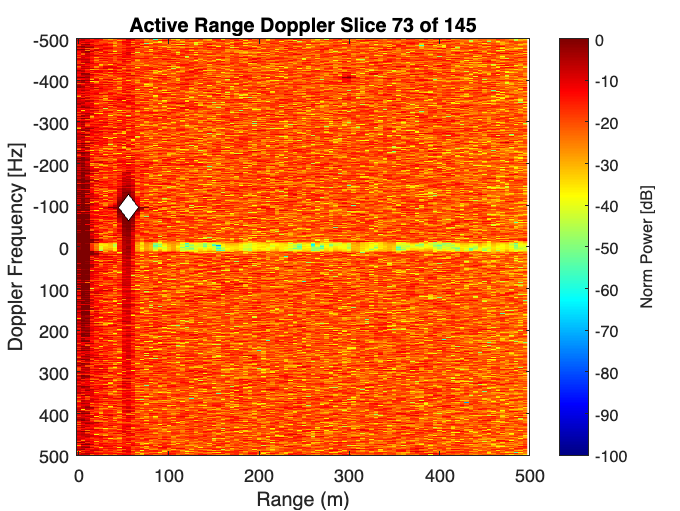

fig_name = figure_directory + bracket + figure_title;
savefig(figure_title)
saveas(fig, fig_name, 'png')

## Quantify Signal and Noise

active_signal; % output from slice_SNR function [dB]
active_noise; % output from slice_SNR function [dB]

## User defined SNR input to the awgn function

User defined level of noise desired

active_user_defined_noise = 10  % User defiend SNR value for awgn function

active_user_defined_noise = 10

Take the input data complex array and apply the awgn function

active_inputdata_plus_noise = createArrays(length(active_inputdata),...
    size(active_inputdata{1,1}));
for i=1:length(active_inputdata)
    active_inputdata_plus_noise{1,i} = awgn(active_inputdata{1,i}, active_user_defined_noise,...
        'measured'); % complex + awgn
end

Convert the noise induced complex array to power using the slice_SNR func

active_signal_plus_noise=zeros(1,length(active_inputdata)); % [dB] once func populates
active_noise_plus_noise=zeros(1,length(active_inputdata)); % [dB] once func populates
active_noise_plus_noise_abs=zeros(1,length(active_inputdata)); % absolute mean noise (not dB) once func populates
active_SNR_plus_noise=zeros(1,length(active_inputdata)); % [dB] once func populates
active_slices_range_doppler_plus_noise = createArrays(length(active_inputdata), size(active_inputdata{1,1})); % [dB]
active_slices_range_doppler_plus_noise_abs = createArrays(length(active_inputdata), size(active_inputdata{1,1})); % Absolute
active_signal_idx_plus_noise = zeros(1,length(active_inputdata));

for i=1:length(active_inputdata)
    [active_signal_plus_noise(i),active_noise_plus_noise(i),active_SNR_plus_noise(i),...
        active_slices_range_doppler_plus_noise{i},...
        active_signal_idx_plus_noise(i), active_noise_plus_noise_abs(i),...
        active_slices_range_doppler_plus_noise_abs{i}]=slice_SNR(active_inputdata_plus_noise{1,i}, active_roi_indices_rows, active_roi_indices_cols);
end  

Visualise the slice chosen by the user both with & without awgn applied at complex stage

figure
figure_title = (inputstructure.name +...
    ' Range Doppler Slice '...
    + k + ' of ' + length(active_inputdata));
fig = figure;

subplot(2, 1, 1);
imagesc(x,y,active_slices_range_doppler{1, k},[-dynamic_range 0])
title(figure_title);
ylabel('Doppler Velocity [m/s]');
xlabel('Range (m)');
% User to define limits of the colorbar
clim([-50 0]) % -dynamic_range
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;

subplot(2, 1, 2);
imagesc(x,y,active_slices_range_doppler_plus_noise{1, k},[-dynamic_range 0])
title(figure_title + ' +' + active_user_defined_noise + 'dB Noise at Complex Stage');
ylabel('Doppler Velocity [m/s]');
xlabel('Range (m)');
% User to define limits of the colorbar
clim([-50 0]) % -dynamic_range
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;

Save figures to data directory

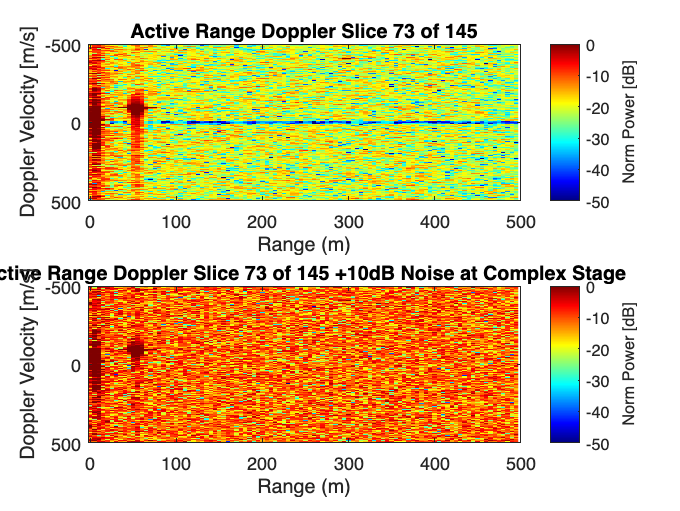

fig_name = figure_directory + bracket + figure_title;
savefig(figure_title)
saveas(fig, fig_name + " baseline to noise comparison", 'png')

## Plot SNR against Time (?) for all slices of Active data

active_SNR_delta = active_SNR - active_SNR_plus_noise;
figure
figure_title = (inputstructure.name + ' SNR for '...
    + length(active_inputdata) + ' Slices');
fig = figure;
plot(1:length(active_SNR), active_SNR, ...
    1:length(active_SNR_plus_noise), active_SNR_plus_noise, ...
    1:length(active_SNR_delta), active_SNR_delta)
title(figure_title);
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("SNR", 'SNR + Noise')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf length(active_SNR)]);   % Range Limit
grid minor

Save figure to repo

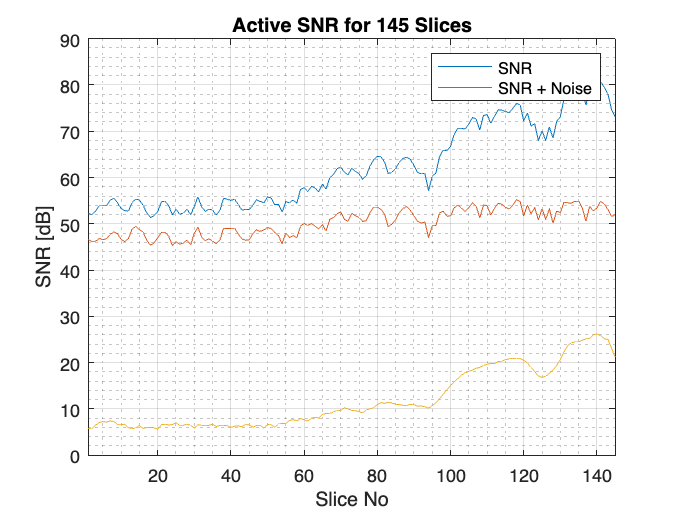

fig_name = figure_directory + bracket + figure_title;
savefig(figure_title)
saveas(fig, fig_name, 'png')

Mean of all Slices - Signal, Noise & SNR

% SNR
active_mean_SNR = mean(active_SNR) % [dB]

active_mean_SNR = 62.2783

active_mean_SNR_plus_noise = mean(active_SNR_plus_noise) % [dB]

active_mean_SNR_plus_noise = 50.2517

active_mean_SNR_delta = active_mean_SNR - active_mean_SNR_plus_noise

active_mean_SNR_delta = 12.0267


% Signal % not required becuase it's unchanged but kept for completeness
active_mean_signal = mean(active_signal) % [dB]

active_mean_signal = 41.7676

active_mean_signal_plus_noise = mean(active_signal_plus_noise) % [dB]

active_mean_signal_plus_noise = 41.7647


% Noise
active_mean_noise = mean(active_noise) % [dB]

active_mean_noise = -20.5108

active_mean_noise_plus_noise = mean(active_noise_plus_noise) % [dB]

active_mean_noise_plus_noise = -8.4869

active_mean_noise_delta = active_mean_noise - active_mean_noise_plus_noise

active_mean_noise_delta = -12.0239


disp(['Discuss with MR']);

Discuss with MR


% Noise delta and Signal delta comparable (expected), but the value changed
% and it's relationship to the SNR vlaue input to the awgn func needs to be
% examined.

## Create video of range-Doppler slices

fig =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [1 1 1]
    Position: [616 498 560 420]
       Units: 'pixels'

  Show all properties


i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

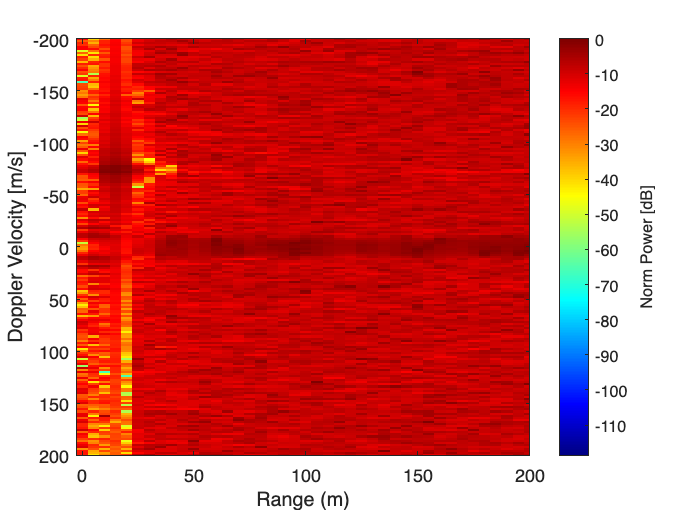

if inputstructure.name == "Active"
    if pc ==1
        video_name = video_directory...
            + bracket + "SNR Active Data"...
            + ".avi";
    elseif pc ==2
        display('pc 3 type path undefined by User')
    elseif pc ==3
        display('pc 3 type path undefined by User')
    else
        display('Undefined by User')
    end    
    video_title = "SNR Active Data";
    dynamic_range = +inf;
    max_range = 200;
    max_doppler = 200;
    frame_rate = 1/(capture_duration/active.number_cpi);
    createVideo(active_slices_range_doppler,frame_rate,...
        active.range_axis,max_range,...
        active.doppler_axis,max_doppler,...
        dynamic_range,video_name,video_title);
end


% only the baseline, what about plus_noise?

## Plot Signal Peak and Matrix Index Across All Slices

Plot each Signal Peak to provide confidence the peak selected is the true target and show anomolies.

**Scatter plot for visualisation**

figure;
fig = figure;
scatter(active_idx_range_axis, active_idx_doppler_axis);
title('Signal Peak - Range Axis Vs Doppler Axis');
xlabel('Range Axis');
ylabel('Doppler Axis');
grid minor;

Save figure to repo

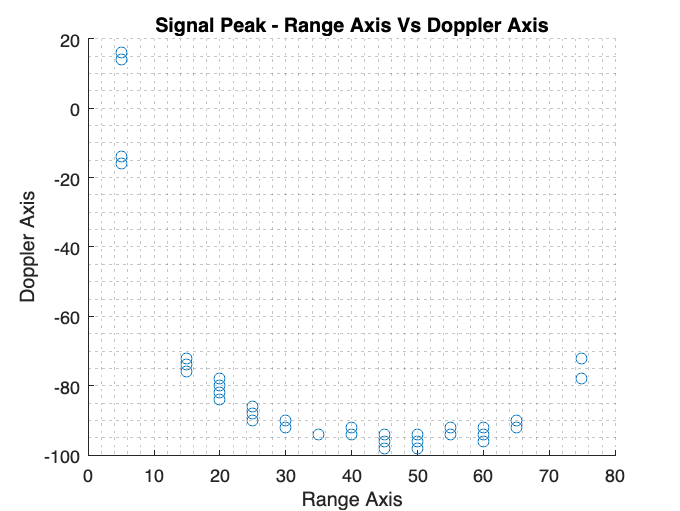

fig_name = figure_directory + bracket + inputstructure.name + ' Signal Peak - Range Vs Doppler';
savefig(figure_title)
saveas(fig, fig_name + '.png') 

**3D Scatter plot for visualisation**

figure;
fig = figure;
scatter3(active_idx_range_axis, active_idx_doppler_axis, 1:length(active_signal));
title('Signal Peak - Range Axis Vs Doppler Axis Vs Slice');
xlabel('Range Axis [m]');
ylabel('Doppler Axis [m/s]');
zlabel('Slice Index');
zlim([1, length(active_signal)])
grid minor;

Save figure to repo

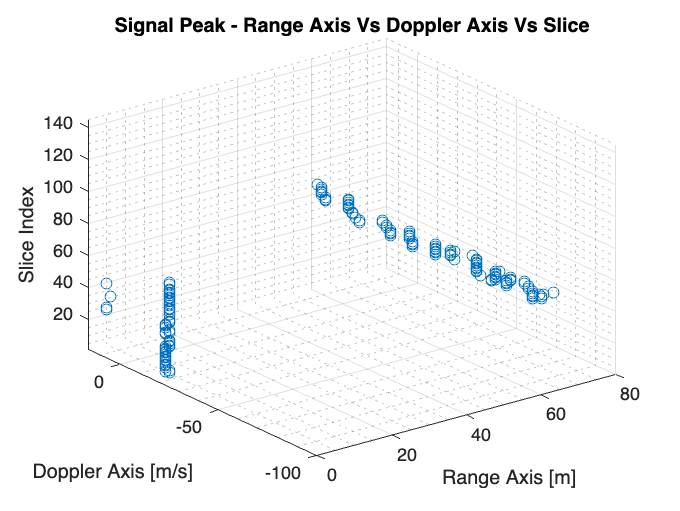

fig_name = figure_directory + bracket + inputstructure.name + ' Signal Peak - Range Vs Doppler Vs Slice';
savefig(figure_title)
saveas(fig, fig_name + '.png')

**Subplot Visualising Range Axis Vs Slice & Doppler Axis Vs Slice**

figure;
fig = figure;
subplot(2,1,1)
scatter(1:length(active_signal), active_idx_range_axis);
title('Range Axis Vs Slice');
xlabel('Slice Index');
ylabel('Range Axis [m]');
xlim([1, length(active_signal)])
grid minor;

subplot(2,1,2)
scatter(1:length(active_signal), active_idx_doppler_axis);
title('Doppler Axis Vs Slice');
xlabel('Slice Index');
ylabel('Doppler Axis');
xlim([1, length(active_signal)])
grid minor;
disp('The subplot visualisation shows that, prior to slice 59, the signal peak being selected is not the true target in the scene.')

The subplot visualisation shows that, prior to slice 59, the signal peak being selected is not the true target in the scene.


The subplot visualisation shows that, prior to slice 59, the signal peak being selected is not the true target in the scene.

Save figure to repo

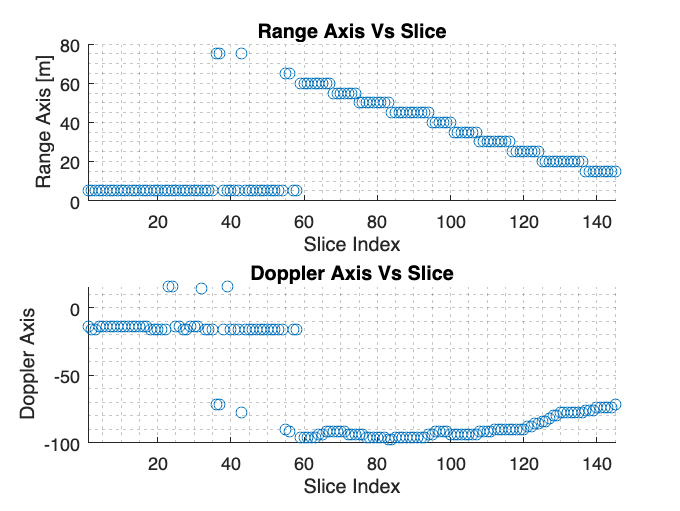

fig_name = figure_directory + bracket + inputstructure.name + ' Signal Peak subplots - Range Vs Slice and Doppler Vs Slice';
savefig(figure_title)
saveas(fig, fig_name + '.png') 